# Juan Pablo Arango Lizcano y Alejandro Padilla, Calculos:

## Tarea #2 Masa resorte

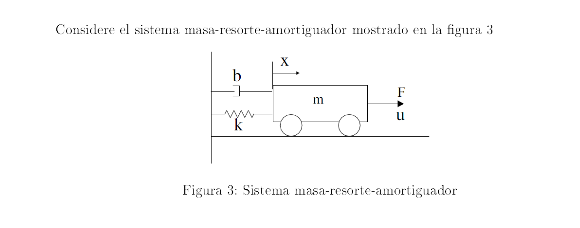


syms m b k s kd kp ki
m=1;
b=10;
k=20;
ts=2.5;
wn=2.29;
z=0.7;
num=[1/m];
den=[1 b/m k/m];
G=tf(num,den);
step(G);
%[re,im]=pol2cart(0.409,0.669);
pd=(s^2+2*wn*z+wn^2)*(s+5*wn);
GG=(1/m)/(s^2+(b/m)*s+(k/m));
CC=(kd*s^2+kp*s+ki)/s;
H=simplify(GG*CC/(1+GG*CC))
[x,pc]=numden(H)
Pc=fliplr(coeffs(pc,s));
pd=fliplr(coeffs(pd,s));
eqns= Pc==pd;
[kd,kp,ki]=vpasolve(eqns,[kd kp ki]);
Ts=ts/10;
%TUSTIN PID transform
q0= kp+((ki*Ts)/2)+kd/Ts
q1=((ki*Ts)/2)-kp-((2*kd)/Ts)
q2=kd/Ts

## Tarea #3 Citerio de Jury Y transformacion

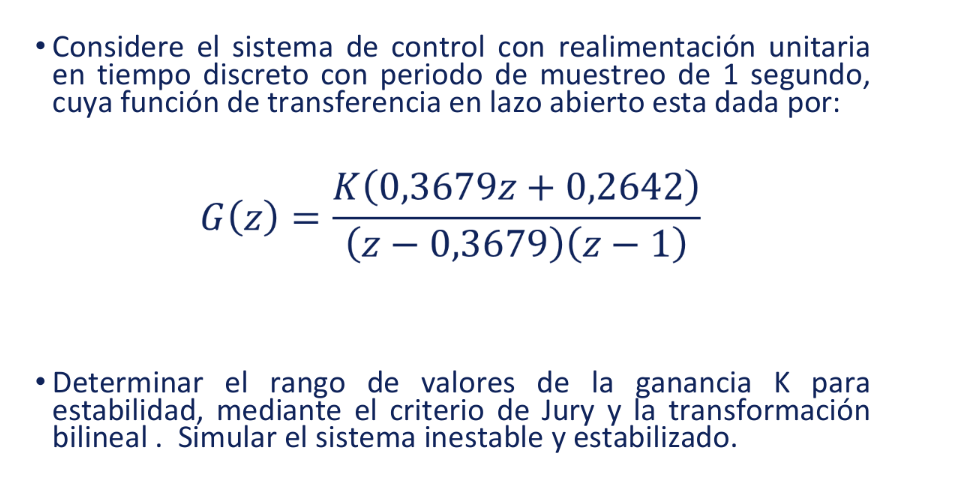

syms z k r
Hz=(k*(0.3679*z+0.2642))/((z^2)+(0.3679*k-1.3679)*z+(0.2642*k+0.3679))
Hr=simplify(subs(Hz,z,((r+1)/(r-1))))
k=2
Num=k*[0.3679 0.2642]
den=[1 0.3679*k-1.3679 0.2642*k+0.3679]
[p,z]=pzmap(Num,den)
pzmap(Num,den)
axis([-1 1 -1 1])
zplane(z,p)
Num2=[0.3679 0.2642];
den2=[1 -1.3679 0.3679];
[p2,z2]=pzmap(Num2,den2);
pzmap(p2,z2)
axis([-1 1 -1 1])
zplane(z2,p2)